## Complex Phase Diagram

A generic state diagram is shown here. Note the line dividing Region 1 and Region 2 is an exponential curve.

Write a program to ask the user to choose a value for Variable A and Variable B. Determine the region on the diagram in which these values lie. Then, recreate the graph, indicating to the user where their chosen value is on the graph using a marker, and issue a statement to the Command Window stating to the user the outcome of their choice.

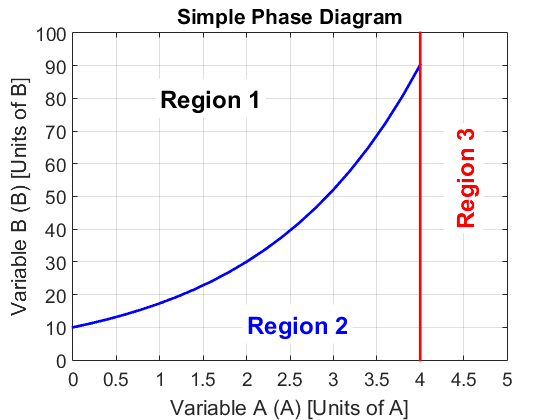

% Housekeeping
clc
clear
close all

% Create Graph of Experimental Data
LXexp=[0 2 2.5 4];
LYexp=[10 30 40 90];

% Determine model parameters using POLYFIT
C=polyfit(LXexp, log(LYexp), 1)

C =     0.5499    2.3046


m=C(1)

m = 0.5499

b=exp(C(2))

b = 10.0199


% Create Theoretical data series with model results
LXth=0:.1:4

LXth =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000


LYth=b*exp(m*LXth)

LYth =    10.0199   10.5863   11.1848   11.8171   12.4851   13.1909   13.9366   14.7244   15.5568   16.4362   17.3654   18.3470   19.3842   20.4800   21.6377   22.8609   24.1532   25.5186   26.9612   28.4853   30.0956   31.7969   33.5944   35.4935   37.5000   39.6199   41.8596   44.2260   46.7261   49.3675   52.1583   55.1068   58.2220   61.5133   64.9907   68.6646   72.5463   76.6473   80.9802   85.5581   90.3947



% Create graph of region lines, including both curved and horizontal line
figure()
plot(LXth,LYth,'b'); hold on;
plot([4 4], [0,100])

%Format plot
axis([0 5 0 100])
grid on
xlabel('Variable A (A) [Units of A]')
ylabel('Variable B (B) [Units of B]')
title('Simple Phase Diagram')
set(gca,'FontSize',14)
set(gca,'XTick',0:0.5:5);
set(gca,'YTick',0:10:100);

% Place region labels on graph
text(1,80, 'Region 1', 'FontSize',18, 'FontWeight','bold', 'BackgroundColor','w')
text(2,11, 'Region 2', 'Color','b', 'FontSize',18, 'FontWeight','bold','BackgroundColor','w')
text(4.5,40,'Region 3', 'Color','r', 'FontSize',18, 'FontWeight','bold','BackgroundColor','w', 'rotation', 90)

% Get user data
A=input("Enter A")

A = 3

B=input('Enter B')

B = 3

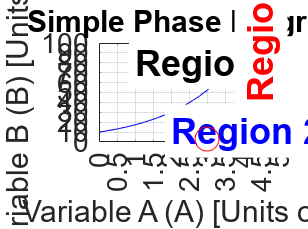

% Add user data to graph

hold on;
plot (A,B,'ro','MarkerSize',12)

% Determine region using if
if A>=4
    Region=3;
elseif B>=b*exp(m*A)
    Region=1
else 
    Region=2
end

Region = 2

% Output information to Command Window
fprintf('this is region %0.0f',Region)

this is region 2